# Cartpend & LTI Parameters 

clear all, close all, clc

global A
global B
global control

m = 1;
M = 5;
L = 2;
g = -10;
d = 1;

b = 1; % pendulum up (b=1)

A = [0 1 0 0;
    0 -d/M b*m*g/M 0;
    0 0 0 1;
    0 -b*d/(M*L) -b*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; b*1/(M*L)];

eig(A)

ans =          0
   -2.4311
   -0.2336
    2.4648


rank(ctrb(A,B))

ans = 4

# Timing Parameters

dt = 0.02;
t_total = 10;
t_attack = 5;
t_span = 0:dt:t_total;

# Simulation Settings

% LQR controller
Q = [1 0 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1];
R = .0001;
K = lqr(A,B,Q,R);

x0 = [0; 0; pi-.1; 0];  % initial condition

wr = [1; 0; pi; 0];      % reference position
u=@(x) -K*(x - wr);       % control law

% ref_fuc = @(i) 2-mod(floor(i*dt/4),2);
% ref = zeros(size(t_span,2),1);
% for i = 1:length(ref)
%     ref(i,1) = ref_fuc(i);
% end

# Simulation - No attacks

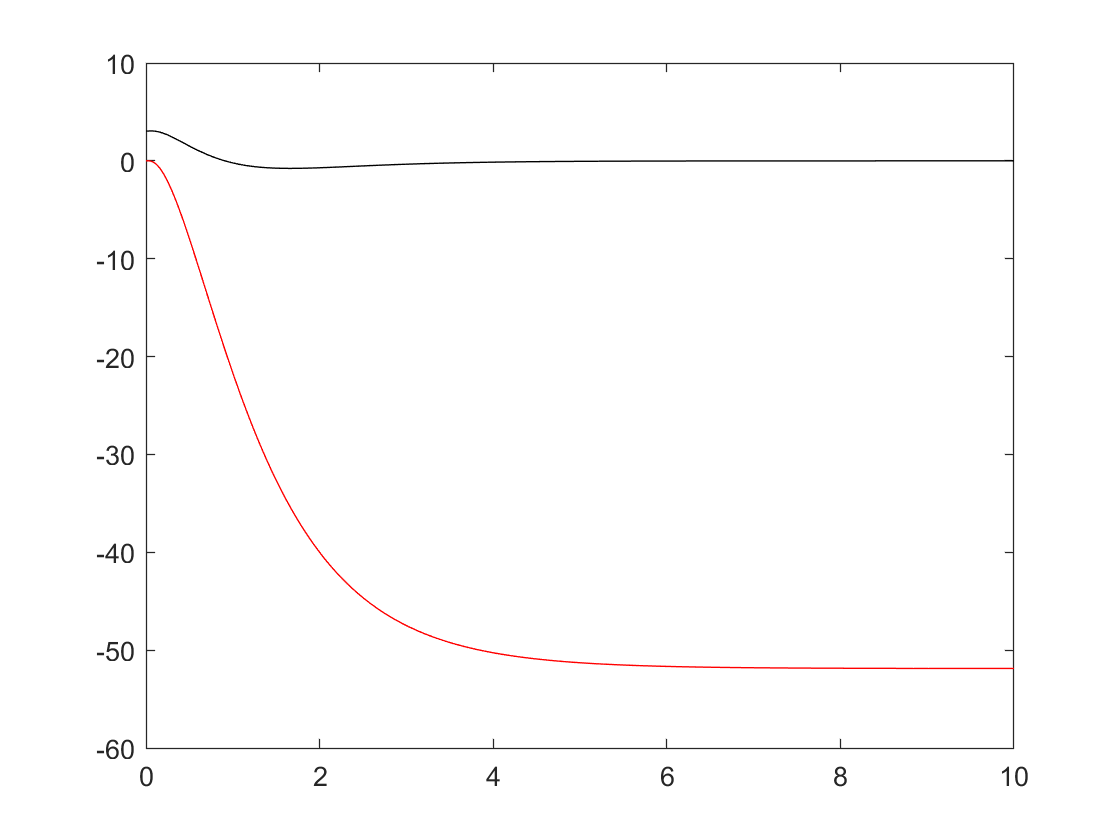

'drawpend' is not found in the current folder or on the MATLAB path, but exists in:
    D:\WorkSpace\RTSS2020\invertedPendulum\recoveryTest
    D:\WorkSpace\DataDrivenControl\CH08

Change the MATLAB current folder or add its folder to the MATLAB path.

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;

for i = 2:(t_total/dt+1)
    control = u(xlast);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,x(:,1),'r',t_span,x(:,3),'k')

# Simulation - Attack, No recovery

x = zeros(size(t_span,2),size(x0,1));  % actual state
x_dirty = zeros(size(t_span,2),size(x0,1));  % measurement state

x(1,:) = x0';
x_dirty(1,:) = x0';
xlast = x0;
x_dirty_last = x0;
attack_type = "force";

for i = 2:(t_total/dt+1)
    if i > t_attack/dt
        x_dirty_last = attack(attack_type, x_dirty_last);
    end
    input = u(x_dirty_last);
    [~,xtemp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,input),(0:dt:dt),xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    
    [~,x_dirty_temp] = ode45(@(t,x)pendcart(x,m,M,L,g,d,input),(0:dt:dt),x_dirty_last);
    x_dirty_last = x_dirty_temp(end,:);
    x_dirty(i,:) = x_dirty_last;
    x_dirty_last = x_dirty_last';
end

plot(t_span,x(:,1),'r',t_span,x(:,3),'k')

for k=1:10:length(t_span)
    drawpend(x(k,:),m,M,L);
end

# Simulation - Attack, With recovery

% x = zeros(size(t_span,2),size(x0,1));  % actual state
% x_dirty = zeros(size(t_span,2),size(x0,1));  % measurement state
% 
% x(1,:) = x0';
% x_dirty(1,:) = x0';
% xlast = x0;
% x_dirty_last = x0;
% 
% detected = 0;
% reset = 0;
% control = u;
% attack_type = "force";
% 
% for i = 2:(t_total/dt+1)
%     % detection here
%     if i > (t_attack+1)/dt
%         detected = 1;
%     end
%     % end of detection 
%    
%     if i > t_attack/dt 
%         if detected
%             % recovery here
%             if ~reset
%                 control = u;
%                 x_dirty_last = xlast;
%                 reset = 1;
%                 disp('recoverd!');
%             end
%             % end of recovery
%         else
%             x_dirty_last = attack(attack_type, x_dirty_last);
%         end
%     end 

t_attack = 5;
t_detected = 6;
% recovery steps
k = 15;
inputs = zeros(k,1);

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;

x_dirty = zeros(size(t_span,2),size(x0,1));
x_dirty(1,:) = x0';
x_dirty_last = x0;


% # of measurements
% y = zeros(size(t_span,2),1);  
% y(1,:) = C * x0;
% y_dirty = zeros(size(t_span,2),1);  
% y_dirty(1,:) = C * x0;

attack_type = "alter";

% flag
attacked = 0;
last_normal = 0;
detected = 0;
reset = 0;

for i = 2:(t_total/dt+1)
    % detection here
    if i == (t_detected)/dt
        detected = 1;
    end
    % end of detection 
        
    if i > t_attack/dt
        if detected
            % recovery here
            if ~reset
                reset = 1;
                disp('recoverd!');
                [Ad, Bd] = LTI_translation(A,B,dt);
                initial_set_lo = xlast;
                initial_set_up = xlast
                errorbound = [0.3; 100];
                target_set_lo = [ref(i,1);0] - errorbound
                target_set_up = [ref(i,1);0] + errorbound
                
                utemp = recovery_control(Ad, Bd, k, initial_set_lo, initial_set_up, target_set_lo, target_set_up);
                inputs = utemp((length(utemp)-k+1):end,1);
            end
            % end of recovery  
        else
            if ~attacked
                last_normal = y(i-1,1);
                attacked = 1;
            end
            if strcmp(attack_type,'delay')
                %             y_dirty(i-1,1) = last_normal;
                delay_step = 50;
                y_dirty(i-1,1) = y(i-delay_step,1);
            elseif strcmp(attack_type,'alter')
                %y_dirty(i-1,1) = last_normal + 0.001*(i-t_attack/dt)
                y_dirty(i-1,1) = y(i-1,1) - 5;
            elseif strcmp(attack_type,'replay')
                y_dirty(i-1,1) = y(0+(i-t_attack/dt));
            end
        end
    end
    
    % PID control
    if i<t_detected/dt || i>=t_detected/dt + k
        error_dirty = ref(i,1) - y_dirty(i-1,1);
        pid_update(error_dirty, dt);
    else
        % recovery input
        index = i-t_detected/dt+1
        control = inputs(index,1)
    end
    
    input = control(x_dirty_last);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
    
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    x_dirty_last = x_dirty_temp(end,:);
    x_dirty(i,:) = x_dirty_last;
    x_dirty_last = x_dirty_last';
    
end

Array indices must be positive integers or logical values.


plot(t_span,x(:,1),'r',t_span,x(:,3),'k')

for k=1:10:length(t_span)
    drawpend(x(k,:),m,M,L);
end

function dxdt = dynamics(t, x)

global A;
global B;
global control;

dxdt = A*x + B*control;

end